I=load("dataIU.mat").I

I =     0.0342
    0.0399
    0.0481
    0.0599
    0.0750
    0.1115
    0.1294
    0.1545
    0.1773
    0.1914


U=load("dataIU.mat").U

U =    -0.0210
   -0.0280
   -0.0386
   -0.0539
   -0.0734
   -0.1196
   -0.1416
   -0.1729
   -0.2009
   -0.2182


h=scatter(U,I)

h =   Scatter - 属性:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [-0.0210 -0.0280 -0.0386 -0.0539 -0.0734 -0.1196 -0.1416 -0.1729 -0.2009 -0.2182 -0.2409 -0.2651 -0.2947 -0.3303 -0.3755 -0.3965 -0.4266 -0.4330 -0.4688 -0.4841 -0.5102 -0.6190 -0.7838 -0.9025 -1.0609 -1.6023 -2.0274 -2.4079 … ]
              YData: [0.0342 0.0399 0.0481 0.0599 0.0750 0.1115 0.1294 0.1545 0.1773 0.1914 0.2103 0.2304 0.2548 0.2851 0.3237 0.3421 0.3683 0.3740 0.4057 0.4197 0.4429 0.5436 0.7028 0.8240 0.9943 1.3260 1.4543 1.6103 1.8002 2.0418 2.3588 2.7915 … ]
           SizeData: 36
              CData: [0 0.4470 0.7410]

  显示 所有属性


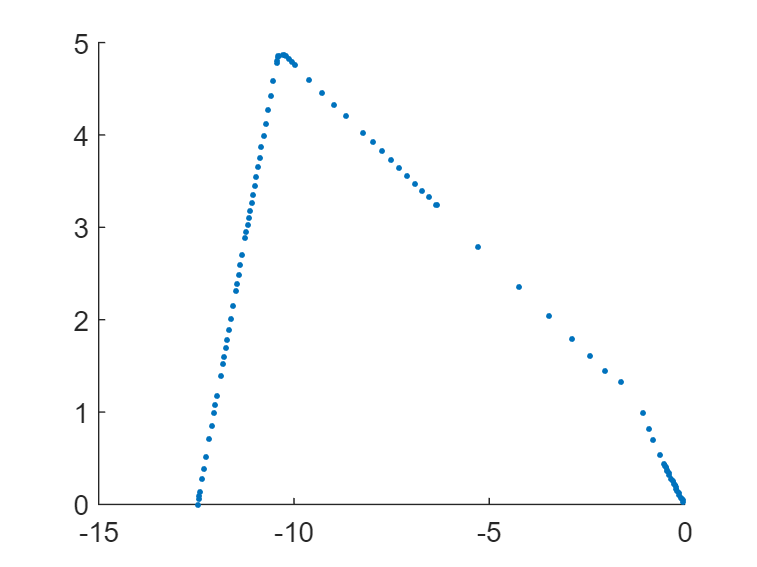

h.Marker='.';
h.LineWidth=0.1;

I1=[];U1=[];I2=[];U2=[];I3=[];U3=[];
for i=1:length(U)
    if U(i)>-1.6
        U1=[U1,U(i)];
        I1=[I1,I(i)];
    end

    if U(i)<-1.6 && U(i)>-10.25
        U2=[U2,U(i)];
        I2=[I2,I(i)];
    end

    if U(i)<-10.25
        U3=[U3,U(i)];
        I3=[I3,I(i)];
    end
end

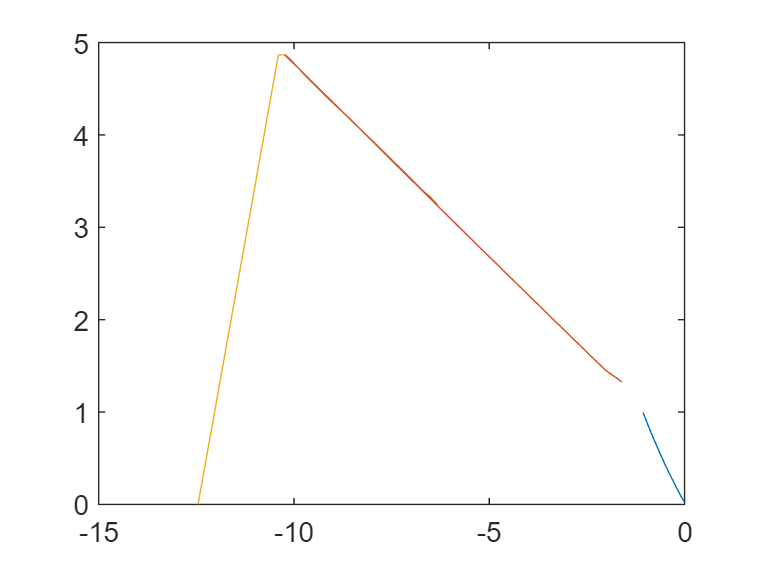

figure
plot(U1,I1)
hold on
plot(U2,I2)
plot(U3,I3)

disp(fitlm(U1,I1))

线性回归模型:
    y ~ 1 + x1

估计系数:
                    Estimate        SE        tStat        pValue  
                   __________    ________    ________    __________

    (Intercept)    -0.0024019    0.004679    -0.51333       0.61262
    x1               -0.90105     0.01067     -84.443    3.5464e-30


观测值数目: 25，误差自由度: 23
均方根误差: 0.0143
R 方: 0.997，调整 R 方 0.997
F 统计量(常量模型): 7.13e+03，p 值 = 3.55e-30


disp(fitlm(U2,I2))

线性回归模型:
    y ~ 1 + x1

估计系数:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)     0.61789    0.0058735     105.2    1.2905e-34
    x1             -0.41498    0.0007909    -524.7     4.728e-52


观测值数目: 27，误差自由度: 25
均方根误差: 0.0108
R 方: 1，调整 R 方 1
F 统计量(常量模型): 2.75e+05，p 值 = 4.73e-52


disp(fitlm(U3,I3))

线性回归模型:
    y ~ 1 + x1

估计系数:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)     29.238       0.10711    272.97    1.7562e-75
    x1              2.3463     0.0094087    249.37    1.1208e-73


观测值数目: 48，误差自由度: 46
均方根误差: 0.0424
R 方: 0.999，调整 R 方 0.999
F 统计量(常量模型): 6.22e+04，p 值 = 1.12e-73


f1=@(x)-0.0024019-0.90105*x;
f2=@(x)0.61789-0.41498*x;
f3=@(x)29.238+2.3463*x;

f2(-10.3648)

ans = 4.9191

a1=fzero(@(x)f1(x)-f2(x),-1)

a1 = -1.2761

a2=fzero(@(x)f2(x)-f3(x),-1)

a2 = -10.3648

figure
h=scatter(U,I)

h =   Scatter - 属性:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [-0.0210 -0.0280 -0.0386 -0.0539 -0.0734 -0.1196 -0.1416 -0.1729 -0.2009 -0.2182 -0.2409 -0.2651 -0.2947 -0.3303 -0.3755 -0.3965 -0.4266 -0.4330 -0.4688 -0.4841 -0.5102 -0.6190 -0.7838 -0.9025 -1.0609 -1.6023 -2.0274 -2.4079 … ]
              YData: [0.0342 0.0399 0.0481 0.0599 0.0750 0.1115 0.1294 0.1545 0.1773 0.1914 0.2103 0.2304 0.2548 0.2851 0.3237 0.3421 0.3683 0.3740 0.4057 0.4197 0.4429 0.5436 0.7028 0.8240 0.9943 1.3260 1.4543 1.6103 1.8002 2.0418 2.3588 2.7915 … ]
           SizeData: 36
              CData: [0 0.4470 0.7410]

  显示 所有属性


h.Marker='o';
h.LineWidth=0.5

h =   Scatter - 属性:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [-0.0210 -0.0280 -0.0386 -0.0539 -0.0734 -0.1196 -0.1416 -0.1729 -0.2009 -0.2182 -0.2409 -0.2651 -0.2947 -0.3303 -0.3755 -0.3965 -0.4266 -0.4330 -0.4688 -0.4841 -0.5102 -0.6190 -0.7838 -0.9025 -1.0609 -1.6023 -2.0274 -2.4079 … ]
              YData: [0.0342 0.0399 0.0481 0.0599 0.0750 0.1115 0.1294 0.1545 0.1773 0.1914 0.2103 0.2304 0.2548 0.2851 0.3237 0.3421 0.3683 0.3740 0.4057 0.4197 0.4429 0.5436 0.7028 0.8240 0.9943 1.3260 1.4543 1.6103 1.8002 2.0418 2.3588 2.7915 … ]
           SizeData: 36
              CData: [0 0.4470 0.7410]

  显示 所有属性


h.SizeData=10

h =   Scatter - 属性:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [-0.0210 -0.0280 -0.0386 -0.0539 -0.0734 -0.1196 -0.1416 -0.1729 -0.2009 -0.2182 -0.2409 -0.2651 -0.2947 -0.3303 -0.3755 -0.3965 -0.4266 -0.4330 -0.4688 -0.4841 -0.5102 -0.6190 -0.7838 -0.9025 -1.0609 -1.6023 -2.0274 -2.4079 … ]
              YData: [0.0342 0.0399 0.0481 0.0599 0.0750 0.1115 0.1294 0.1545 0.1773 0.1914 0.2103 0.2304 0.2548 0.2851 0.3237 0.3421 0.3683 0.3740 0.4057 0.4197 0.4429 0.5436 0.7028 0.8240 0.9943 1.3260 1.4543 1.6103 1.8002 2.0418 2.3588 2.7915 … ]
           SizeData: 10
              CData: [0 0.4470 0.7410]

  显示 所有属性


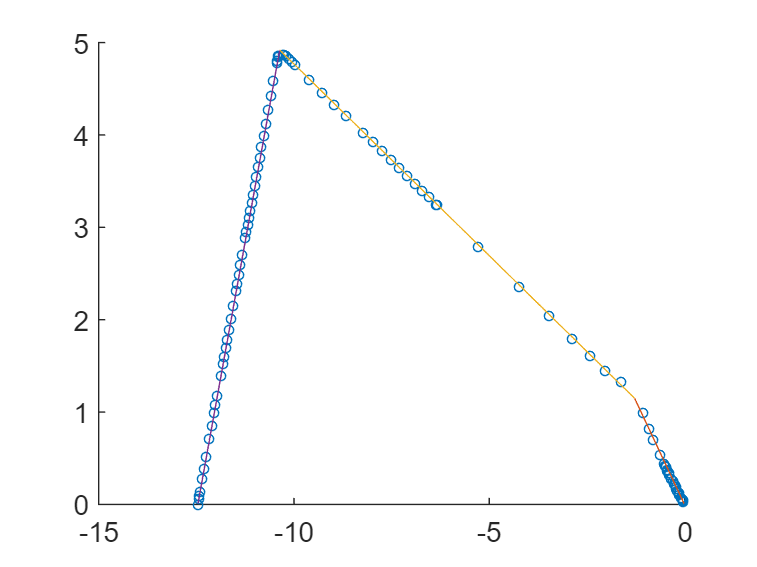

hold on
t=a1:0.01:0;
plot(t,f1(t))
t=a2:0.01:a1;
plot(t,f2(t))
t=min(U):0.01:a2;
plot(t,f3(t))


t=-a1:0.01:0;
plot(t,f1(t))
t=-a2:0.01:-a1;
plot(t,-f2(t))
t=-min(U):0.01:-a2;
plot(t,-f3(t))

figure
t=-15:0.01:15

t =   -15.0000  -14.9900  -14.9800  -14.9700  -14.9600  -14.9500  -14.9400  -14.9300  -14.9200  -14.9100  -14.9000  -14.8900  -14.8800  -14.8700  -14.8600  -14.8500  -14.8400  -14.8300  -14.8200  -14.8100  -14.8000  -14.7900  -14.7800  -14.7700  -14.7600  -14.7500  -14.7400  -14.7300  -14.7200  -14.7100  -14.7000  -14.6900  -14.6800  -14.6700  -14.6600  -14.6500  -14.6400  -14.6300  -14.6200  -14.6100  -14.6000  -14.5900  -14.5800  -14.5700  -14.5600  -14.5500  -14.5400  -14.5300  -14.5200  -14.5100


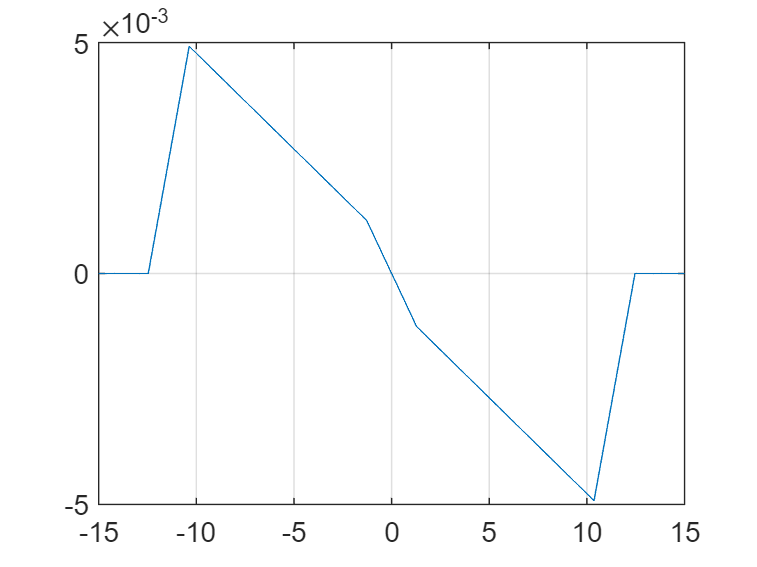

for i=1:length(t)
    II(i)=Intensity(t(i));
end
plot(t,II)
grid on

Intensity(0)

ans = -0.0024

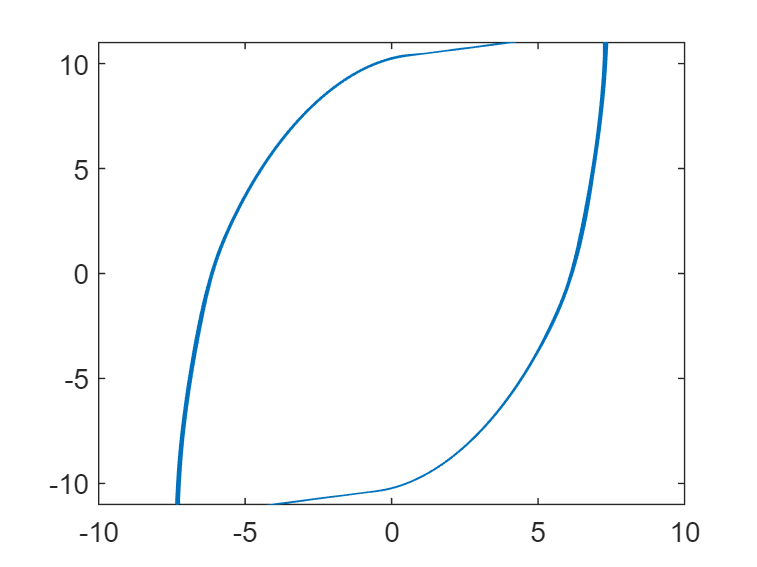

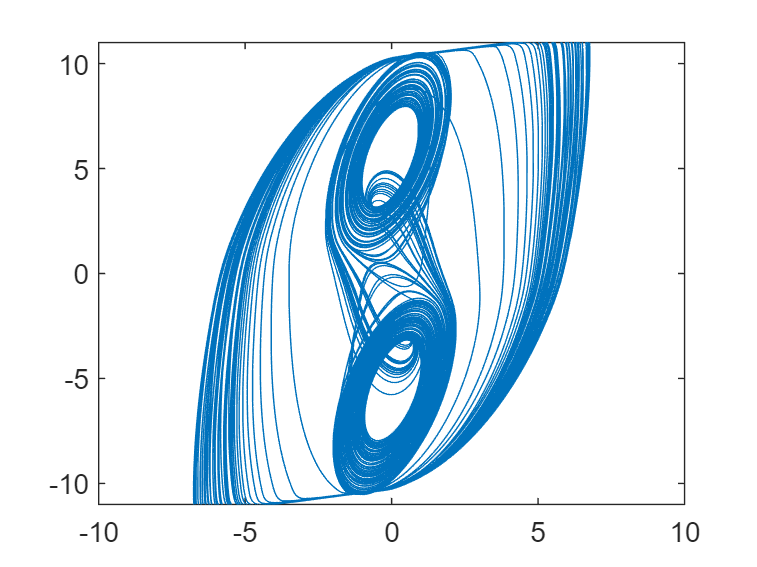

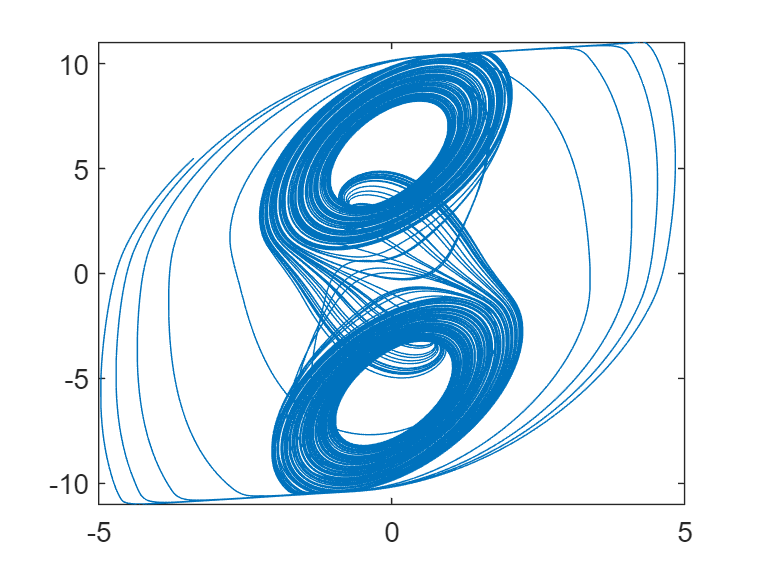

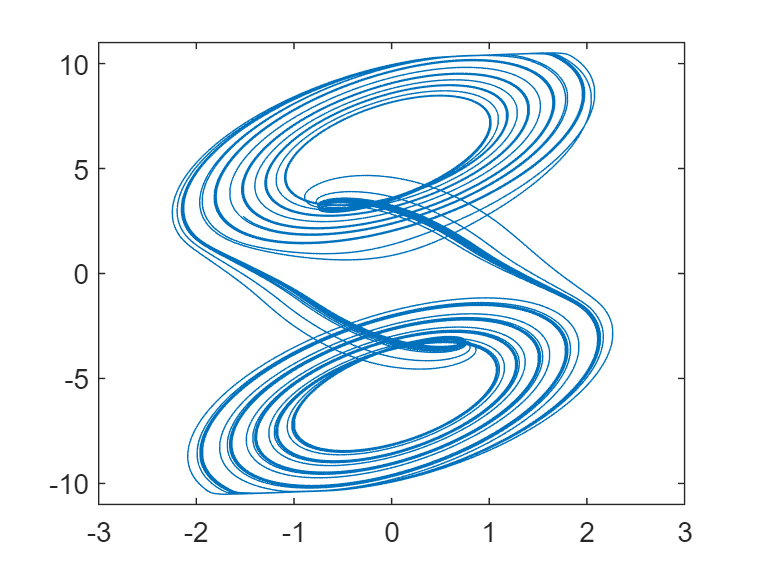

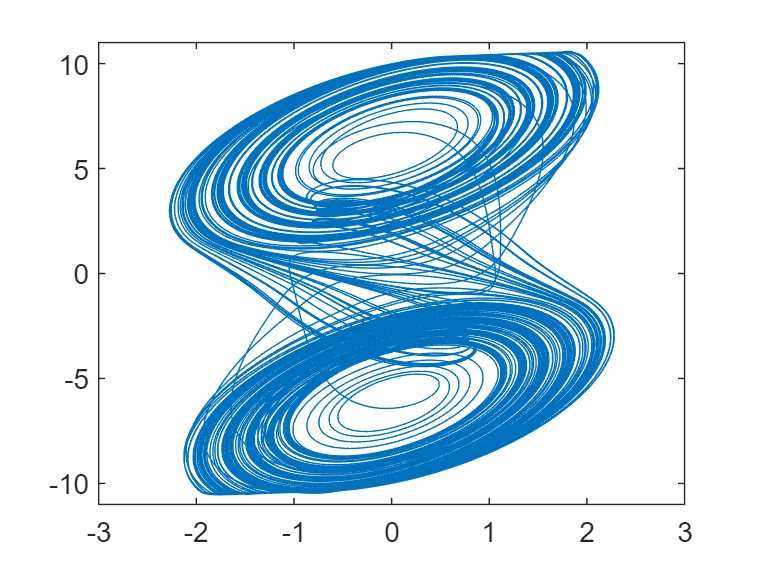

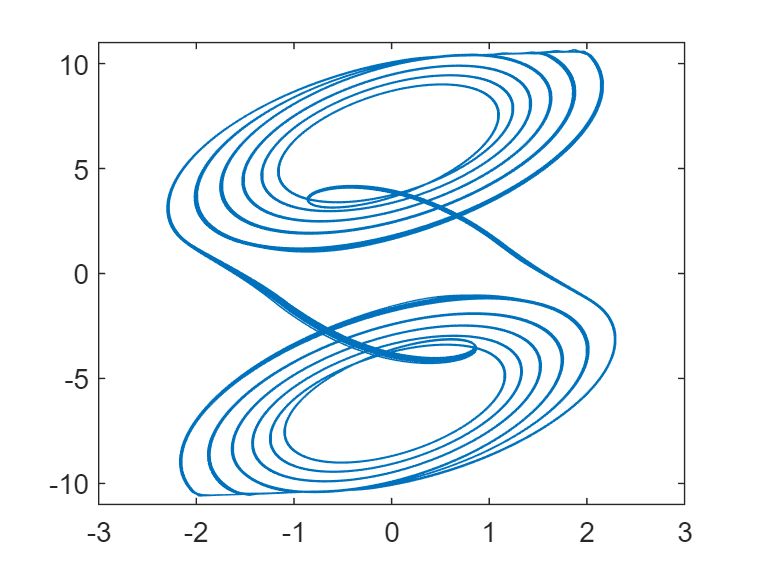

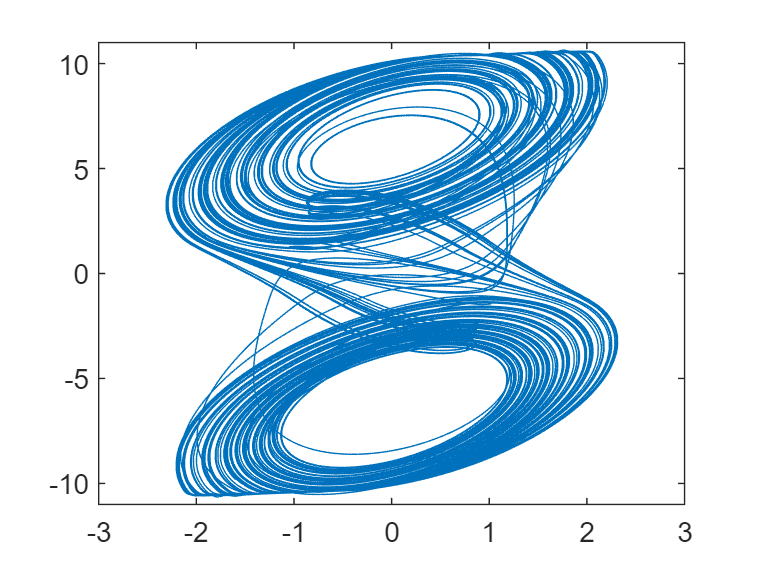

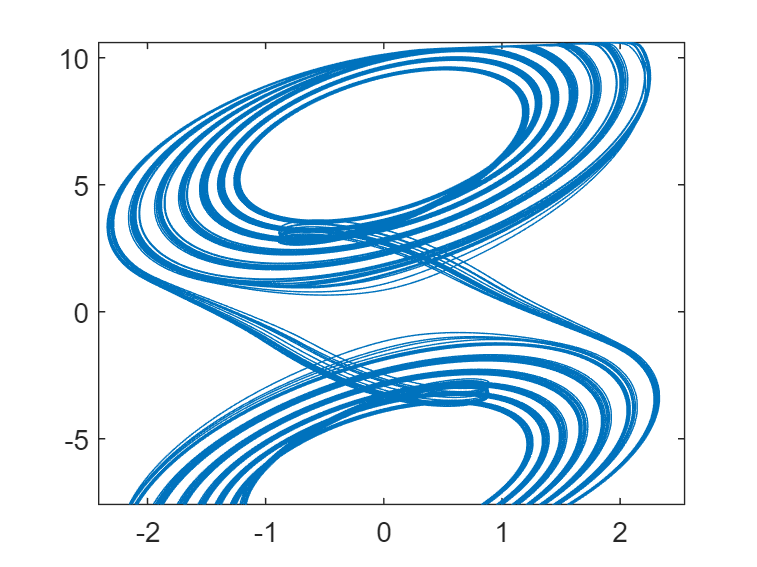

for R0=1900:10:2100
    i=(R0-1900)/10+1;
[t,u]=ode45(@(t,u)model_prime(t,u,R0),[0:0.000001:0.1],[5,5,1]);
figure
plot(u(20000:end,2),u(20000:end,1))
ylim([-11,11])
end

function I=Intensity(U)
f1=@(x)-0.0024019-0.90105*x;
f2=@(x)0.61789-0.41498*x;
f3=@(x)29.238+2.3463*x;

f4=@(x)0.0024019-0.90105*x;
f5=@(x)-0.61789-0.41498*x;
f6=@(x)-29.238+2.3463*x;

a1=fzero(@(x)f1(x)-f2(x),-1);
a2=fzero(@(x)f2(x)-f3(x),-1);

I=0;
if U<=0 && U>=a1
    I=f1(U);
elseif U<a1 && U>=a2
    I=f2(U);
elseif U<a2 && U>=-12.4568
    I=f3(U);
elseif U<=12.4568
    I=0;
end

if U>0 && U<=-a1
    I=f4(U);
elseif U>-a1 && U<=-a2
    I=f5(U);
elseif U>-a2 && U<=12.4568
    I=f6(U);
elseif U>=12.4568
    I=0;
end

I=I*10^(-3);
end
    
function a=model_prime(t,u,R)
c1=10^(-8);c2=10^(-7);
L=18.8*10^(-3);
a=[1/c1*(1/R*(u(2)-u(1))-Intensity(u(1)));
    1/c2*(1/R*(u(1)-u(2))+u(3));
    -1/L*u(2)];
end